%% Ejercicio 4: Sugeno 2 entradas
fis = sugfis("Name","Sugeno2D");

% Métodos (AND suele ser min o prod)
fis.AndMethod = "min";   % prueba "prod" para comparar
fis.OrMethod  = "max";

%% Inputs: X, Y en [-5,5]
fis = addInput(fis,[-5 5],"Name","X");
fis = addInput(fis,[-5 5],"Name","Y");

% MFs para X
fis = addMF(fis,"X","zmf",[-1 1],"Name","Pequeño");
fis = addMF(fis,"X","smf",[-1 1],"Name","Grande");

% MFs para Y
fis = addMF(fis,"Y","zmf",[-1 1],"Name","Pequeño");
fis = addMF(fis,"Y","smf",[-1 1],"Name","Grande");

%% Output: Z (Sugeno)
fis = addOutput(fis,[-5 12],"Name","Z"); % rango amplio para tu superficie

% En Sugeno, MFs de salida lineales: z = a*x + b*y + c
fis = addMF(fis,"Z","linear",[-1  1  1],"Name","R1"); % -x + y + 1
fis = addMF(fis,"Z","linear",[ 0 -1  3],"Name","R2"); % -y + 3
fis = addMF(fis,"Z","linear",[-1  0  3],"Name","R3"); % -x + 3
fis = addMF(fis,"Z","linear",[ 1  1  2],"Name","R4"); %  x + y + 2

%% Reglas
% Índices MFs: X(Peq=1, Gra=2), Y(Peq=1, Gra=2), Z(R1=1,R2=2,R3=3,R4=4)
% Formato sugfis: [idxX idxY idxZ weight AND]
ruleList = [
    1 1 1 1 1
    1 2 2 1 1
    2 1 3 1 1
    2 2 4 1 1
];
fis = addRule(fis,ruleList);

%% Probar entradas
tests = [
    -4 -4
    -4  4
     4 -4
     4  4
     0  0
     1 -2
];
z = evalfis(fis,tests);
disp(table(tests(:,1),tests(:,2),z,'VariableNames',{'X','Y','Z'}));

    X     Y      Z  
    __    __    ____

    -4    -4       1
    -4     4      -1
     4    -4      -1
     4     4      10
     0     0    2.25
     1    -2       2



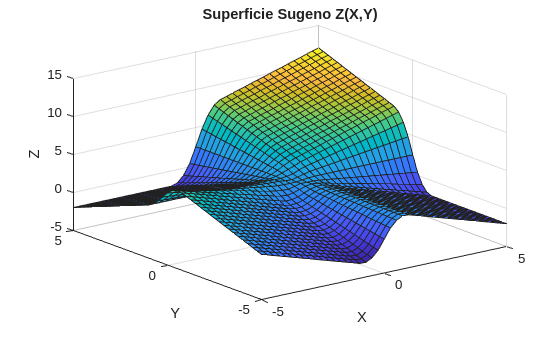


%% Superficie (malla)
[xg,yg] = meshgrid(linspace(-5,5,41), linspace(-5,5,41));
zg = arrayfun(@(a,b) evalfis(fis,[a b]), xg, yg);

figure;
surf(xg,yg,zg);
xlabel("X"); ylabel("Y"); zlabel("Z"); title("Superficie Sugeno Z(X,Y)");